## Import Geometry

thermalmodel = createpde('thermal','steadystate');
importGeometry(thermalmodel,'qPiston.stl');
pdegplot(thermalmodel, 'FaceAlpha',.75, 'FaceLabels', 'on')

## Generate Mesh

tic
generateMesh(thermalmodel, 'Hmax', 1.5);
timeToGenerateMesh = toc

timeToGenerateMesh = 4.5283

thermalmodel.Mesh

ans =   FEMesh with properties:

             Nodes: [3×119891 double]
          Elements: [10×80180 double]
    MaxElementSize: 1.5000
    MinElementSize: 0.7500
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


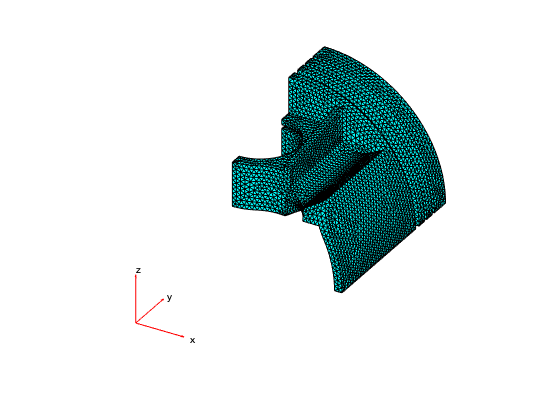

pdemesh(thermalmodel)

## Setup Material Properties

thermalProperties(thermalmodel, 'Cell', 1, 'ThermalConductivity', 0.175728);

## Setup the Boundary Conditions

T1 = 638.3;
q1 = .3537;
h1 = q1/T1;
thermalBC(thermalmodel,'Face', 51, 'ConvectionCoefficient', h1, 'AmbientTemperature', T1);
T2 = 573;
h2 = 0.07*q1/T2;
thermalBC(thermalmodel, 'Face', 24, 'ConvectionCoefficient', h2, 'AmbientTemperature', T2);
T3 = 345.5;
h3 = 0.19*q1/T3;
thermalBC(thermalmodel, 'Face', [13 17 21], 'ConvectionCoefficient', h3, 'AmbientTemperature', T3);
T4 = 345.5;
h4 = 0.04*q1/T4;
thermalBC(thermalmodel, 'Face', [16 20], 'ConvectionCoefficient', h4, 'AmbientTemperature', T4);
T5 = 345.5;
h5 = 0.1*q1/T5;
thermalBC(thermalmodel, 'Face', 12, 'ConvectionCoefficient', h5, 'AmbientTemperature', T5);
T6 = 383;
h6 = 0.11*q1/T6;
thermalBC(thermalmodel, 'Face', 30, 'ConvectionCoefficient', h6, 'AmbientTemperature', T6);
T7 = 383;
h7 = 0.42*q1/T7;
thermalBC(thermalmodel, 'Face', 50, 'ConvectionCoefficient', h7, 'AmbientTemperature', T7);

## Thermal Static Analysis Simulation

tic
thermalResults = solve(thermalmodel);
timeToThermalAnalysis = toc

timeToThermalAnalysis = 7.5747

## Plot Temperature Map

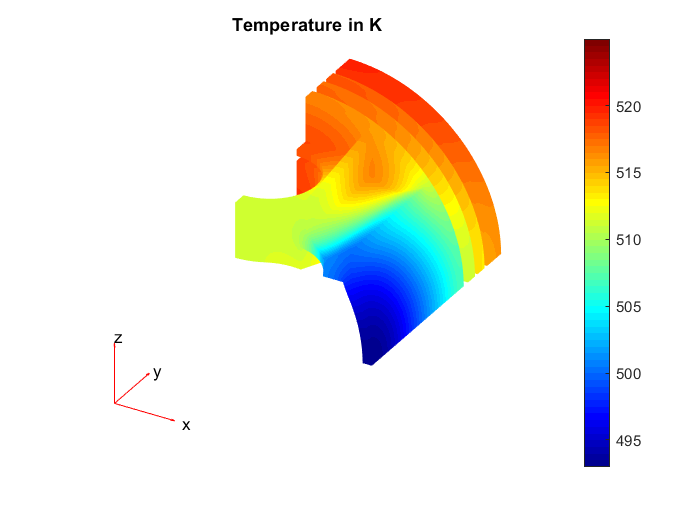

pdeplot3D(thermalmodel,'ColorMapData',thermalResults.Temperature)
title('Temperature in K')
colorbar

## Thermo-Structural Analysis Model Definition and Material Properties

thermoStructuralModel = createpde('structural', 'static-solid');
thermoStructuralModel.Geometry = thermalmodel.Geometry;
thermoStructuralModel.Mesh = thermalmodel.Mesh;
structuralProperties(thermoStructuralModel, 'Cell', 1, 'YoungsModulus', 67*1e9, 'PoissonsRatio', 0.33, 'CTE', 23*1e-6);

## Setup Boundary Conditions

structuralBC(thermoStructuralModel, 'Face', 3, 'Constraint', 'fixed');
structuralBC(thermoStructuralModel, 'Face', [53 54 55], 'Constraint', 'symmetric');
structuralBC(thermoStructuralModel, 'Face', [53 54 55], 'Constraint', 'roller');
structuralBodyLoad(thermoStructuralModel, 'Temperature', thermalResults);
thermoStructuralModel.ReferenceTemperature = 300;

## Thermo-Structural Analysis Simulation

tic
thermoStructuralResults = solve(thermoStructuralModel);
timeToThermoStructualAnalysis = toc

timeToThermoStructualAnalysis = 180.5016

## Plot Deformation and Von Mises Stress Map

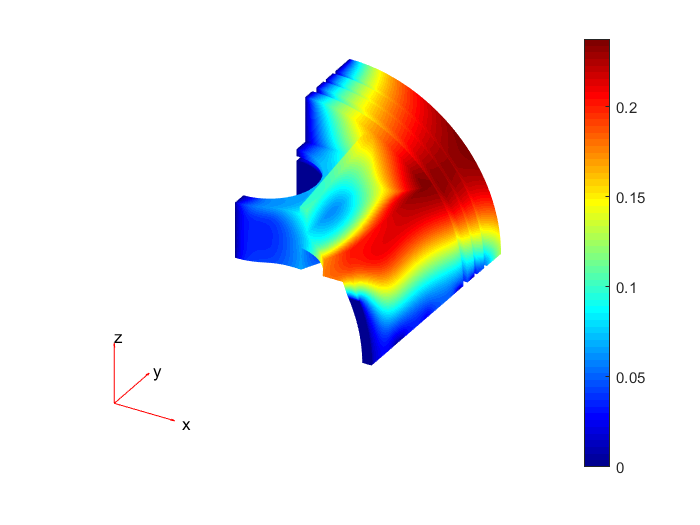

pdeplot3D(thermoStructuralModel,'ColorMapData',thermoStructuralResults.Displacement.Magnitude, ...
                          'Deformation',thermoStructuralResults.Displacement, ...
                          'DeformationScaleFactor',1)

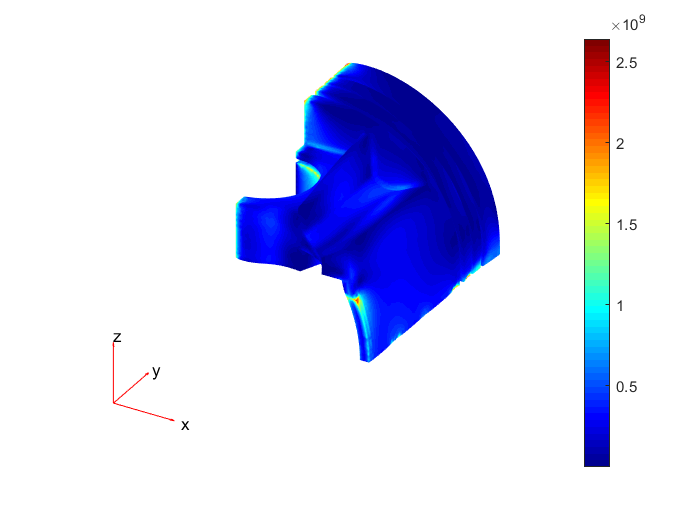

pdeplot3D(thermoStructuralModel,'ColorMapData',thermoStructuralResults.VonMisesStress,'Deformation', thermoStructuralResults.Displacement,'DeformationScaleFactor',10)